# Figures showing correlation plots 

Look at how the velocity correlation changes as a function of time and space. 

clear all
close all

% Observations
obs_traj = load ('../data/traj_09_03_13_clean.mat');

% delete sections in the Scotia Sea.
obs_traj.Yc(obs_traj.Xc>-82) = NaN;
obs_traj.Xc(obs_traj.Xc>-82) = NaN;

% use forward differencing to estimate the velocity 
Unew = nan*obs_traj.Xc;
Vnew = nan*obs_traj.Xc;
dt = 1*24*3600; 
cor = 110*1e3; 

Unew(1:end-1,:) = diff(obs_traj.Xc)*cor.*cosd(obs_traj.Yc(1:end-1,:))/dt; 
Vnew(1:end-1,:) = diff(obs_traj.Yc)*cor/dt; 

obs_traj.Uc = Unew; 
obs_traj.Vc = Vnew; 

% Models
d=[4, 10];

for i =1:length(d)
    [mod_traj(i).X, mod_traj(i).Y, mod_traj(i).U, mod_traj(i).V, mod_traj(i).T, depth(i)] = loadpairs(d(i));
    
    % get the velocity from forward differencing (will be important for structure functions)
    Unew = nan*mod_traj(i).X;
    Vnew = nan*mod_traj(i).X;
    dt = 1*24*3600; 
    cor = 110*1e3; 
    
    Unew(1:end-1,:) = diff(mod_traj(i).X)*cor.*cosd(mod_traj(i).Y(1:end-1,:))/dt; 
    Vnew(1:end-1,:) = diff(mod_traj(i).Y)*cor/dt; 
    
    mod_traj(i).U = Unew; 
    mod_traj(i).V = Vnew; 
    
    mod_traj(i).U(mod_traj(i).U==-999) = NaN;
    mod_traj(i).V(mod_traj(i).V==-999) = NaN;
    mod_traj(i).Y(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).U(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).V(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).X(mod_traj(i).X>360-70) = NaN;
    
end

depth = -472.4093

depth = -1.0048e+03

depth = -1.6855e+03

% separation time series from observatios
sep_obs = calculate_seperation_timeseries(obs_traj);

%% Settings
plevel = [500 1000 1800]; % how large are the bins
ndays  = 100; % how long to track a pair
pdiff  = 200; % what is the p difference that we allow.

% Distance pairs
distance_class(1).dist = [10,15]*1e3;
distance_class(2).dist = [30,35]*1e3;

%% get the right pairs
for i =1:length(distance_class)
    for j=1:length(plevel)-1
        [obs_pairs(j,i), obs_sep(j,i)] = find_pairs(sep_obs, distance_class(i).dist, [plevel(j) plevel(j+1)], pdiff, ndays);
    end
end

%% calc sep models
for i = 1:length(distance_class)
    for j =1:length(d)
        mod_sep(j,i) = model_sep_calcs(mod_traj(j), distance_class(i).dist); 
    end
end

%% Obs 
for i =1:length(distance_class)
    for j =1:length(plevel)-1
        for n = 1:500
            y = randsample(obs_pairs(j,i),obs_pairs(j,i),true);
            
            Obs_cor(n,j,i) = correlation_func(obs_sep(j,i).sep(y), ndays);
            
            Cobs(:,n,j,i) = Obs_cor(n,j,i).c; 
            robs(:,n,j,i) = Obs_cor(n,j,i).r; 
            
        end
    end
end

[Cobsmean, Cobsci] = errbar4shaded(Cobs);
robsmean = squeeze(nanmean(robs,2));

%% model  
for i =1:length(distance_class)
    for j=1:length(d)
        Mod_cor(j,i) = correlation_func(mod_sep(j,i).sep, ndays) ;
        Cmod(:,j,i) = Mod_cor(j,i).c; 
        rmod(:,j,i) = Mod_cor(j,i).r; 
    end
end

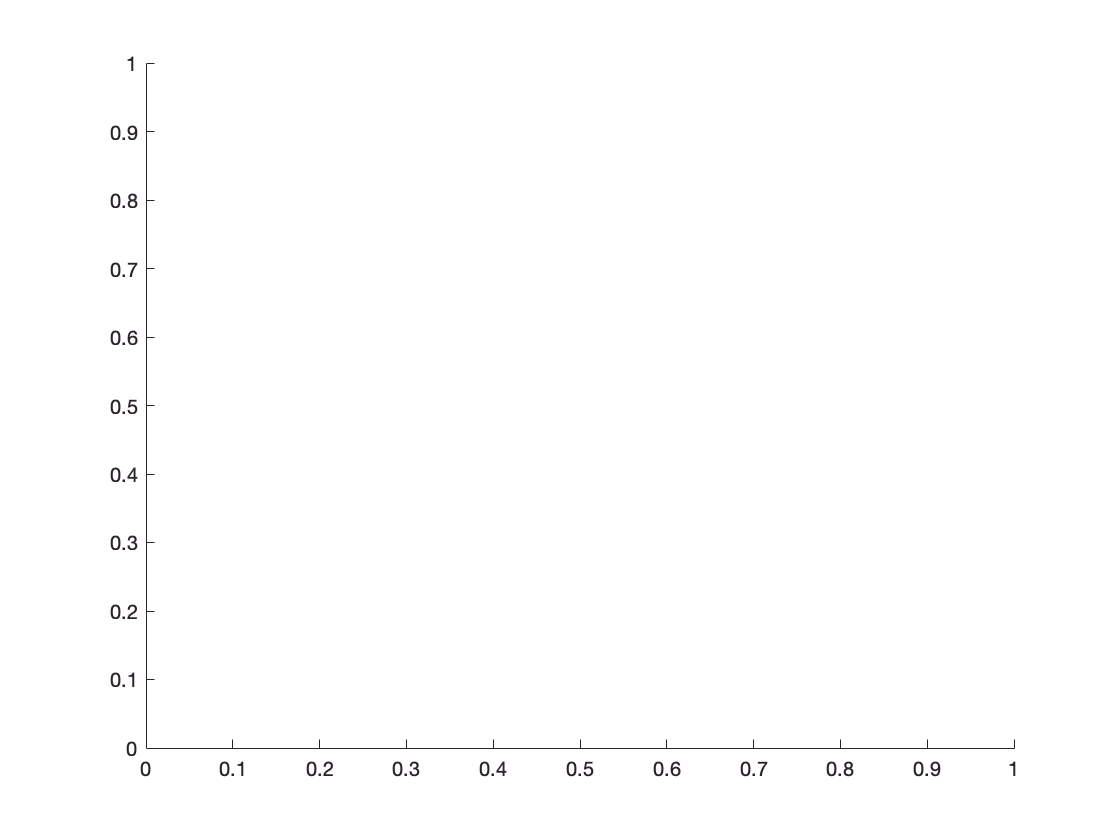

T = 0:99; 
colors = get(gca, 'ColorOrder'); 

col_num = [1,4; 2, 5];

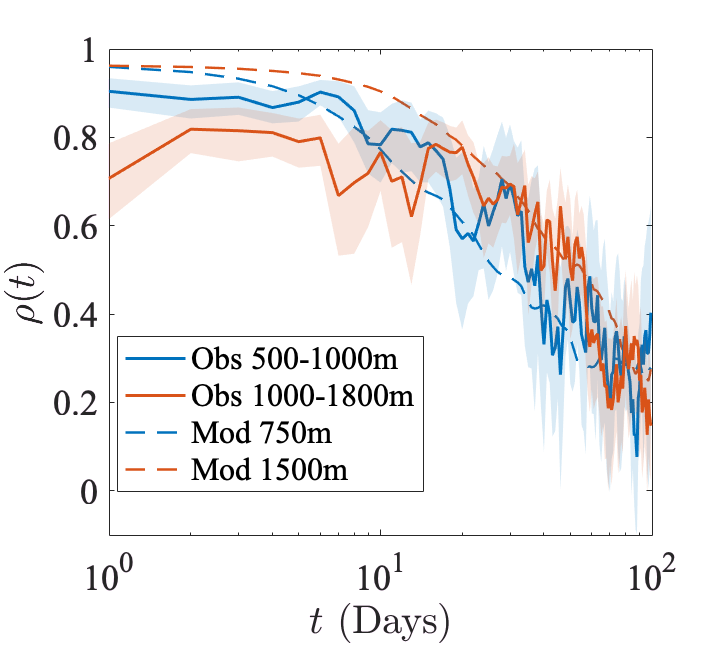

% figure with same D_0 but at different depths
% D_0 = 10-15km


clear h g 

figure('unit','inches','pos',[0. 0. 5 4.5])

for j=1:length(d)
    g(j) = semilogx(T+0.001, Cmod(:,j,1),'--', 'color', colors(col_num(j,1),:),  'linewidth', 1.2);
    hold all 
end

% shallow 
h(1)= shadedErrorBar_semilogx(T+0.001, Cobsmean(:,1,1), Cobsci(:,:,1,1), ...
                    {'-','linewidth',1.5,'color',colors(col_num(1,1),:)},1);
hold all 
h(2)= shadedErrorBar_semilogx(T+0.001, Cobsmean(:,2,1), Cobsci(:,:,2,1), ...
                    {'-','linewidth',1.5,'color',colors(col_num(2,1),:)},1);

               
                
axis([1 100 -0.1 1])
legend([h(1).mainLine,h(2).mainLine, g(1), g(2)], ...
    {'Obs 500-1000m', 'Obs 1000-1800m', 'Mod 750m', 'Mod 1500m'}, 'location', 'best') 

set(gca,'FontSize', 18, 'fontname','times')

xlabel('$t$ (Days)', 'Interpreter','Latex')
ylabel('$\rho (t)$' , 'Interpreter','Latex')

print('corr_t_10.eps', '-depsc','-r400')

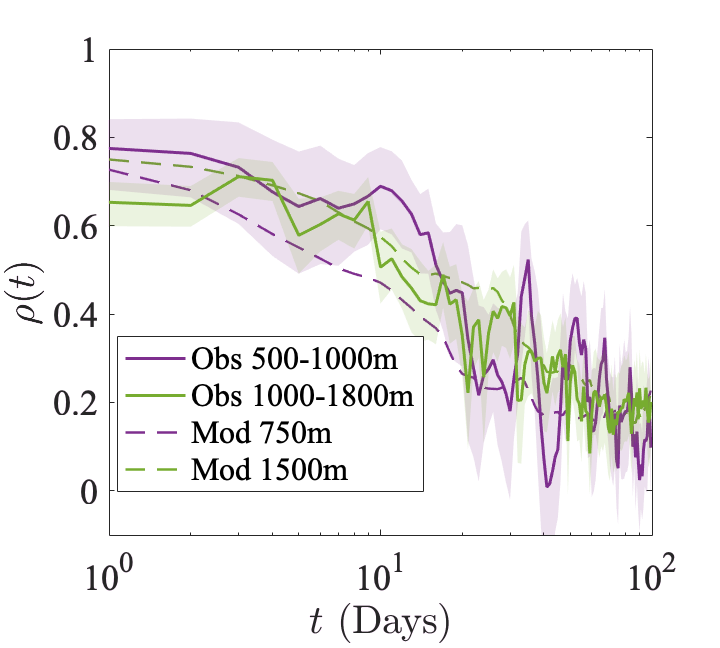

% figure with same D_0 but at different depths
% D_0 = 30-35km

clear h g 

figure('unit','inches','pos',[0. 0. 5 4.5])

for j=1:length(d)
    g(j) = semilogx(T+0.001, Cmod(:,j,2),'--', 'color', colors(col_num(j,2),:), 'linewidth', 1.2);
    hold all 
end

% shallow 
h(1)= shadedErrorBar_semilogx(T+0.001, Cobsmean(:,1,2), Cobsci(:,:,1,2), ...
                    {'-','linewidth',1.5,'color',colors(col_num(1,2),:)},1);
hold all 
h(2)= shadedErrorBar_semilogx(T+0.001, Cobsmean(:,2,2), Cobsci(:,:,2,2), ...
                    {'-','linewidth',1.5,'color',colors(col_num(2,2),:)},1);

               
                
axis([1 100 -0.1 1])
legend([h(1).mainLine,h(2).mainLine, g(1), g(2)], ...
    {'Obs 500-1000m', 'Obs 1000-1800m', 'Mod 750m', 'Mod 1500m'}, 'location', 'best') 

set(gca,'FontSize', 18, 'fontname','times')

xlabel('$t$ (Days)', 'Interpreter','Latex')
ylabel('$\rho (t)$' , 'Interpreter','Latex')

print('corr_t_30.eps', '-depsc','-r400')

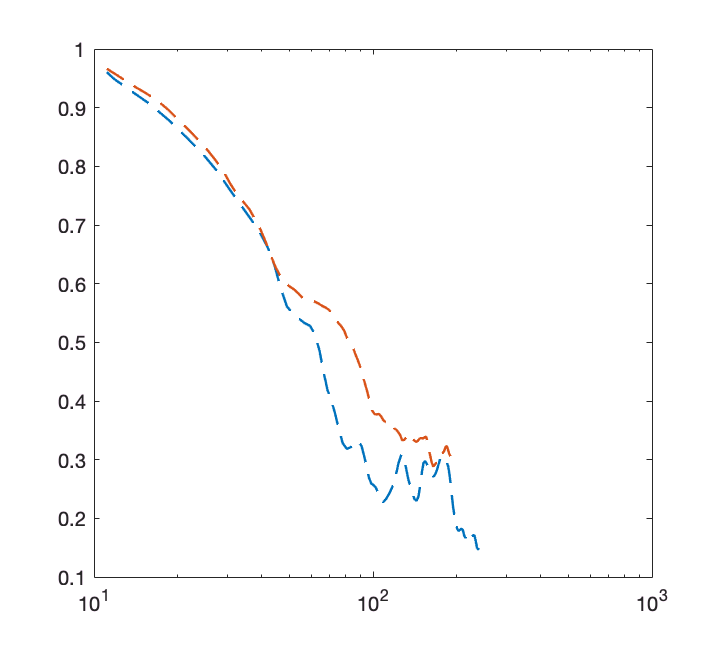

Index exceeds matrix dimensions.

% figure for all with D on x-axis 

clear h g 

figure('unit','inches', 'pos', [0 0 5 4.5])

% D0 = 10
for j=1:length(d)
    g(j) = semilogx(rmod(:,j,1)/1e3, Cmod(:,j,1),'--',  'color', colors(col_num(j,1),:), 'linewidth', 1.2);
    hold all 
end


% D0 = 30 
for j=1:length(d)
    semilogx(rmod(:,j,2)/1e3, Cmod(:,j,2), '--',  'color', colors(col_num(j,2),:), 'linewidth', 1.2);
end

h(1) = semilogx(robsmean(:,1,1)/1e3, Cobsmean(:,1,1), 'linewidth', 1.5, 'color', colors(col_num(1,1),:));

h(2) = semilogx(robsmean(:,1,2)/1e3, Cobsmean(:,1,2),  'linewidth', 1.5, 'color', colors(col_num(1,2),:));

h(3) = semilogx(robsmean(:,2,1)/1e3, Cobsmean(:,2,1), 'linewidth', 1.5, 'color', colors(col_num(2,1),:));

h(4) = semilogx(robsmean(:,2,2)/1e3, Cobsmean(:,2,2),  'linewidth', 1.5, 'color', colors(col_num(2,2),:));


% Initial point marker
for i=1:length(d)
    semilogx(rmod(1,i,1)/1e3, Cmod(1,i,1), 'o',  'color', 'k')

    semilogx(rmod(1,i,2)/1e3, Cmod(1,i,2), 'o',  'color', 'k')
end
semilogx(robsmean(1,1,1)/1e3, Cobsmean(1,1,1), 'o','linewidth', 2, 'color', 'k');
semilogx(robsmean(1,1,2)/1e3, Cobsmean(1,1,2), 'o','linewidth', 2, 'color',  'k');
semilogx(robsmean(1,2,1)/1e3, Cobsmean(1,2,1), 'o','linewidth', 2, 'color',  'k');
semilogx(robsmean(1,2,2)/1e3, Cobsmean(1,2,2), 'o','linewidth', 2, 'color',  'k');


%h(1)= shadedErrorBar_semilogx(robsmean(:,1,1)/1e3, Cobsmean(:,1,1), Cobsci(:,:,1,1), ...
%                    {'-','linewidth',2,'color',colors(1,:)},1);

%h(2)= shadedErrorBar_semilogx(robsmean(:,1,2)/1e3, Cobsmean(:,1,2), Cobsci(:,:,1,2), ...
%                    {'--','linewidth',2,'color',colors(1,:)},1);       

%h(3)= shadedErrorBar_semilogx(robsmean(:,2,1)/1e3, Cobsmean(:,2,1), Cobsci(:,:,2,1), ...
%                    {'-','linewidth',2,'color',colors(2,:)},1);                       
%h(4)= shadedErrorBar_semilogx(robsmean(:,2,2)/1e3, Cobsmean(:,2,2), Cobsci(:,:,2,2), ...
%                    {'--','linewidth',2,'color',colors(2,:)},1);                                       

axis([10 300 -0.1 1])

%legend([h(1),h(3), g(1)], ...
%    {'Obs. 500-1000m', 'Obs. 1000-1800m', 'Mod.'}, 'location', 'best') 

set(gca,'FontSize', 18, 'fontname','times')

xlabel('$r^*$ (km)', 'Interpreter','Latex')
ylabel('$\rho (r^*)$' , 'Interpreter','Latex')

print('corr_r.eps', '-depsc','-r400')
